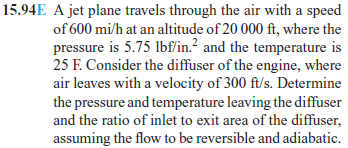

# classes

u = symunit;
air = ig([], 'US');

# inflow properties

Vi = 600*u.mph;
pi = 5.75*u.psi;
Ti = 25*u.Fahrenheit;
ci = sqrt(air.gamma*air.R*f2r(Ti));
ci = simplify(rewrite(combine(ci), 'US'), 'IgnoreAnalyticConstraints', true);
ci = rewrite(ci, u.mph);
ci_vpa = vpa(ci)

$$ci\_vpa = 735.75805862770858911032784805933\,\mathrm{mph}$$

Mi = Vi/ci;
Mi_vpa = vpa(Mi)

$$Mi\_vpa = 0.81548546151038249521330181474852$$

# stagnation properties

po = pi/air.p_po(Mi);
po_vpa = vpa(po)

$$po\_vpa = 8.9017822506025697407758096118033\,\mathrm{psi}$$

To = r2f(f2r(Ti)/air.T_To(Mi));
To_vpa = vpa(To)

$$To\_vpa = 89.462713088172051811852725222707\,\mathrm{{}^{\circ}F}$$

# exit properteis

Ve = 300*u.ft/u.s;
Te = 25*u.Fahrenheit; % ???????
ce = sqrt(air.gamma*air.R*f2r(Te));
ce = simplify(rewrite(combine(ce), 'US'), 'IgnoreAnalyticConstraints', true);
ce_vpa = vpa(ce)

$$ce\_vpa = 1079.1118193206392640284808438204\,\frac{\mathrm{ft}}{s}$$

Me = Ve/ce;
Me_vpa = vpa(Me)

$$Me\_vpa = 0.2780064073330849415499892550279$$

pe = po*air.p_po(Me);
pe_vpa = vpa(pe)

$$pe\_vpa = 8.4364709895578654491867421261563\,\mathrm{psi}$$

Te = To*air.T_To(Me);
Te_vpa = vpa(Te)

$$Te\_vpa = 88.100892441672195146486770299013\,\mathrm{{}^{\circ}F}$$

Ae_Ai = air.A_As(Me)/air.A_As(Mi);
Ae_Ai_vpa = vpa(Ae_Ai)

$$Ae\_Ai\_vpa = 2.111801796849006670975058940134$$